# **ARINC 825 - Loopback**

This example shows you how to do a loopback test with the ARINC 825 blocks using an IO602, IO603 or a IO691 CAN I/O module.

The turnkey ARINC 825 Blockset empowers you to send and receive scheduled CAN messages without having to design your own CAN structure for avionic applications. You will also benefit from a hardware timestamp which enables you to achieve high resolution and an accuracy of ±1 bit time, with very low jitter. Additionally, all channels can have their own scheduling table with an individual minor time frame period.

This example demonstrates the use of scheduled messages on CAN channel 1 and CAN channel 2. Additionally, standard non-scheduled ARINC825 communication between CAN channel 2 and CAN channel 1 is used.

The Simulink model features the [ARINC 825 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc825_setup), [ARINC 825 - Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc825_read), [ARINC 825 - Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc825_write) and the [ARINC 825 - Update Scheduled Message](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc825_update_scheduled_message) blocks using the IO602-2.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO602, IO603 or a IO691 CAN I/O module installed

- Connector cable from the I/O module to four **D-Sub9 connectors**

- Two CAN cables with two D-Sub9 connectors that both contain a termination resistor

- One runtime license for ARINC 825. Refer to the [Runtime Licensing](https://www.speedgoat.com/help/slrt/page/io_main/refentry_runtime_license) documentation for more information

The IO602-4, IO603 or IO691 I/O modules can also be used with the ARINC 825 blocks. To set this up, change the module type in all ARINC 825 blocks to IO602-4, IO603 or IO691.

### Test Setup

In this example, CAN channel 1 and CAN channel 2 are used together. A loopback cable can therefore be used that directly connects these CAN channels. Refer to the pin mapping for your CAN I/O module to connect the required channels: [IO602-4 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_4_pin_mapping) / [IO602-2 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io602_2_pin_mapping) / [IO603 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io603_pin_mapping) / [IO691 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io691_pin_mapping)

Please note that the none of the mentioned I/O Modules include any termination resistors, and the CAN High and CAN Low cables must be terminated externally with a$120\;\Omega$ resistor.

## Initialize and Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_ARINC825_Loopback';
open_system(modelName);

### Model Description

In the Simulink model, the CAN message with ID101 is a scheduled message, configured in the  [ARINC 825 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_arinc825_setup) for channel 1. The message with ID202 is not scheduled and will therefore be treated with lower priority than the scheduled message, should both these messages arrive at the same time in the output buffer. The elements of the CAN message are packed together with either a subsystem containing [Out Bus Element](https://ch.mathworks.com/help/simulink/slref/outbuselement.html) blocks or the [CAN FD Pack](https://mathworks.com/help/vnt/ug/canfdpack.html) block, and the [Bus Selector](https://mathworks.com/help/simulink/slref/busselector.html) block or the [CAN FD Unpack](https://mathworks.com/help/vnt/ug/canfdunpack.html) block is used to access the different properties of the CAN message on the receiving side. This ensures a convenient way of accessing the data and timestamp of the ARINC 825 CAN message received. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check if the loopback is working as expected, open the Simulink scope connected to the CAN Read blocks. Two sine waves with different sample-rates must be displayed:

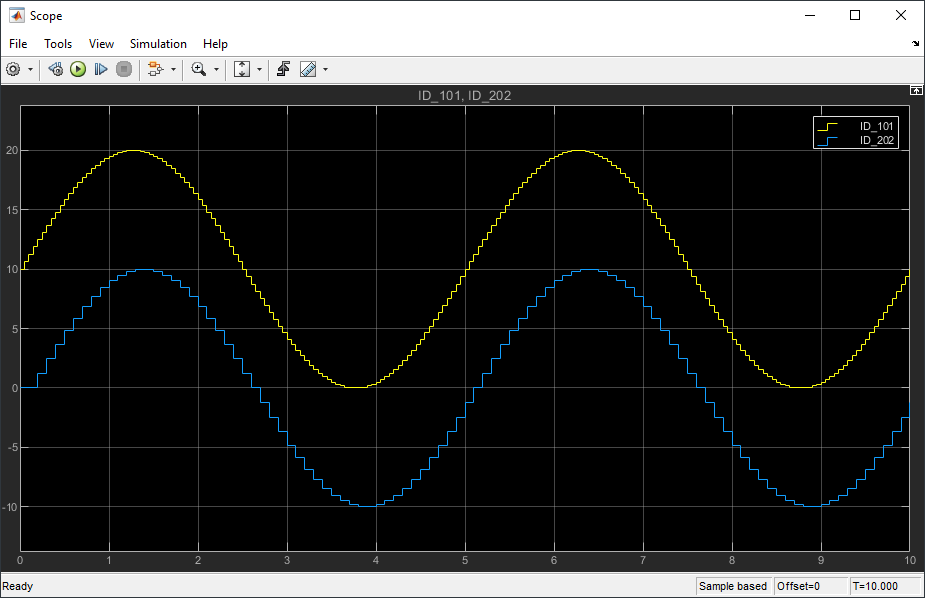

## Additional References

- [ARINC 825 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_arinc825)

- [Description of CAN MESSAGE BUS datatype](https://www.speedgoat.com/help/slrt/page/io_main/refentry_can_ofa_usage_notes)